Q3-Q5

Data storage

clc; clear all; clear figure; clear var
% df1=imread('Images\Image0001.tiff');
patern=load('Images\Labels.mat');pat=struct2table(patern);
% ex=patern.Labels;
dc = dir('Images\*.tiff');dct=struct2table(dc);
Image_table=[dct pat];%make table and concatenate the pattern tag.

%Image data store
ds = imageDatastore("Images\","FileExtensions",'.tiff');%read only tiff files


Q3-Q4

Q4 

since B=max len

Sqaure = A2=$\frac{\left(B^2 \right)}{\;2}=0\ldotp 5\times B^2$ 

$\frac{A_{\textrm{sq}} }{B^2 }=0\ldotp 5$, so $\frac{A_{\textrm{sq}} }{B^2 }$-0.5> 0 then its circle, else is square

Circle = A1=$\pi *{\left(\frac{B}{2}\right)}^2$=0.7854*B^2


$$\frac{A_{\textrm{circle}} }{B^2 }=0\ldotp 7854$$


It is easier to identify whether its cirlce. so, if $1-\frac{A_{\textrm{circle}} }{B^2 }<0\ldotp 2146$ its sa circle. (since edge of morphology will make edge lower a bit.)

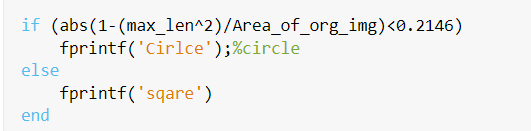

% 
% %load file
% File_no=7;
% df=rdimg(File_no);
% %set up strel 
% % r=4;n=8;
% SE_disk = strel('disk',15,0);
% 
% 
% 
% imcls_plt(df,SE_disk);
% title('image close')
% test=(im2bw(imcls_plt(df,SE_disk)));
% 
% 
% %Hough transformation Get H, T, R and plot
% [H,T,R]=hh(test);
% %peaks identify
% peaks_id=4;
% P  = hh_lineplt(H,T,R,peaks_id);
% 
% 
% fgp=3;mini_l=4;
% lines = houghlines(test,T,R,P,'FillGap',fgp,'MinLength',mini_l);
% %canvavs for origin
% figure
% figure(9)
% imshow(df,'InitialMagnification', 800), hold on
% title('Max len')
% % exportgraphics(figure(9),'Q5_sq_.png',"Resolution",300)
% 
% 
% 
% max_len=hh_linMax(lines)
% Area_max_cir=pi*((max_len/2)^2)
% Area_max_sq=max_len^2
% print('Area of origin')
% 
% Area_of_org_img=sum(test,"all")
% 
% % abs(1-abs((max_len^2/Area_of_org_img)))
% % match_cir=(Area_max_cir)/Area_of_org_imsg
% % match_sq=(Area_max_sq)/Area_of_org_img
% 
% % (max_len^2)/Area_of_org_img;
% % tuning the identification can distinguish circle shape
% % id=abs(1-(max_len^2)/Area_of_org_img);
% % <0.2146
% id=(max_len^2)/Area_of_org_img;
% if (id>1)
%     id
%     fprintf('Cirlce');%circle
% else
%     fprintf('sqare')
%     id
% end

Q5

SE_disk = strel('disk',15,0);

for i=1:length(dc)
%     df=rdimg(i);
%     imcls_plt(df,SE_disk);
%     title('image close')

    test =im2bw(imclose(rdimg(i),SE_disk));
%     test=(im2bw(imcls_plt(df,SE_disk)));
    
H=0;T=0;R=0;%reset    
[H,T,R] = hough(test);
%peaks identify
peaks_id=6;
P  =houghpeaks(H,peaks_id,'threshold',ceil(0.3*max(H(:))));


fgp=3;mini_l=4;
lines=0;
lines = houghlines(test,T,R,P,'FillGap',fgp,'MinLength',mini_l);
%canvavs for origin
% figure, imshow(df), hold on

max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
%    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
%    plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
%    plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end

% max_len=max_len;


% max_len(i)=hh_linMax(lines);

% Area_max_cir=pi*((max_len/2)^2);
% Area_max_sq=max_len^2;


Area_of_org_img=sum(test,"all");

%0 is cirlce
%1 is square
id=max_len^2/Area_of_org_img;
% (max_len^2)/Area_of_org_img>0.1426
if id<1.27
    t(i)=0;%circle
else
    t(i)=1;
end

end



Acc=0;
for i=1:length(dc)
    
    if eq(t(i),Image_table.Labels(i))
        Acc=Acc+1;
    end
end

Accuracy=(Acc/1000)*100

Accuracy = 90.4000

Function

function [max_len,Area_max_cir,Area_max_sq,Area_of_org_img]= exp_area_len(img_ps,peaks_id)
%introduce functions
    [H,T,R]=hh(img_ps);
    P  = hh_lineplt(H,T,R,peaks_id);
%     fgp=1;mini_l=2;
    lines = houghlines(test,T,R,P,'FillGap',1,'MinLength',2);
    figure, imshow(df), hold on
    
    max_len=hh_linMax(lines)
    
    % print line and area
    Area_max_cir=pi*((max_len/2)^2)
    Area_max_sq=max_len^2
    print('Area of origin')
    Area_of_org_img=sum(test,"all")
end


function [img,bimg]=rdimg(file)
    ds = imageDatastore("Images\","FileExtensions",'.tiff');
    img=imread(ds.Files{file});
    bimg=im2bw(img);
end


function dil_plt(BW,se)
figure
    subplot(1,2,1)
    BW2 = imdilate(BW,se);
    imshow(BW), title('Original')
    subplot(1,2,2)
    imshow(BW2), title('Dilated')
end

function ero_plt(BW,se)
figure
    subplot(1,2,1)
    BW2 = imerode(BW,se);
    imshow(BW), title('Original')
    subplot(1,2,2)
    imshow(im2bw(BW2)), title('erode')
end

function [BW2]= imcls_plt(BW,se)
figure
    subplot(1,2,1)
    BW2 = imclose(BW,se);
    imshow(BW), title('Original')
    subplot(1,2,2)
    imshow(BW2), title('imclose')
end

function [H,T,R]=hh(img)
%hough function is installed internal
    [H,T,R] = hough(img);
    figure
    imshow(H,[],'XData',T,'YData',R,...
                'InitialMagnification','fit');
    xlabel('\theta'), ylabel('\rho');
    axis on, axis normal, hold on;
end


function [P]=hh_lineplt(H,T,R,peaks_id)
P  = houghpeaks(H,peaks_id,'threshold',ceil(0.3*max(H(:))));
x = T(P(:,2)); y = R(P(:,1));
plot(x,y,'s','color','red');
end

function[len]= hh_linMax(lines)
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end

plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','#FF00FF');
end